clear all

Song = '13B04'; % Choose a song to inspect (but keep track of which ones you used if you do any parameter tuning)
totalstrophenumber = 37; %% Number of stophes in this song
Ne = 0;  % Number of evaluations (how many syllables we compare)
Success = 0;
Falseidentificationsind =[]; % Save the false identifications for analysis
sspcc = []; % ignore this

for k = 1: totalstrophenumber

    k
    [SStot, Xmattest,labelsong, Fs ] = stropheLoader(Song, k, 4, 500,2*1024,44100,1); % load correct labels and calculate spectrograms
    L =length(labelsong); % Number of syllable pairs to evaluate

    % Calculate similarity measure for each pari using SPCC
    spcc = zeros(1,L);
    for i= 1:L

        % spectrograms for the two syllables
        Sx = SStot(:,:,i); 
        Sy = SStot(:,:,i+1);
        [result, r1, r2] = spcc_similarity(Sx,Sy); %  result = SPCC (the similarity measure). ignore r1 and r2.
        sspcc = [sspcc ; r1 r2 labelsong(i)];
        spcc(1,i) = result;
    end
    % Decide if the two syllables are the same or not based on the
    % similarity measure 
    similar = spcc >= 0.67;
   
    evaluation = mod(similar + labelsong,2); %  0= True (we identified correctly) , 1= False . Validate our decision by comparing with the real labels.
    Success = Success + sum(~evaluation); % count the successful evaluations
    Ne = Ne + L; % total number of evaluations
    fel = find(evaluation == 1); % the index of the false evaluations
    fels = k*ones(1,length(fel)); % to which song the false evaluations belong

    Falseidentificationsind = [Falseidentificationsind ; [fel' fels' spcc(fel)' labelsong(fel)']];  % The coloumns are [ syllableIndex stropheNr similarityMeasure actualLabel ]

end

k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

Success/Ne % success rate

ans = 0.8607

Ne % Number of evaluations

Ne = 596

Falseidentificationsind % list of the false identificatioins. The coloumns are [ syllableIndex stropheNr similarityMeasure actualLabel ]

Falseidentificationsind =     1.0000    2.0000    0.7833         0
    9.0000    3.0000    0.8667         0
   12.0000    4.0000    0.8054         0
    4.0000    5.0000    0.7150         0
    2.0000    6.0000    0.7170         0
    6.0000    6.0000    0.8012         0
    5.0000    7.0000    0.7160         0
   10.0000    8.0000    0.6993         0
   13.0000    8.0000    0.8954         0
   15.0000    8.0000    0.7118         0


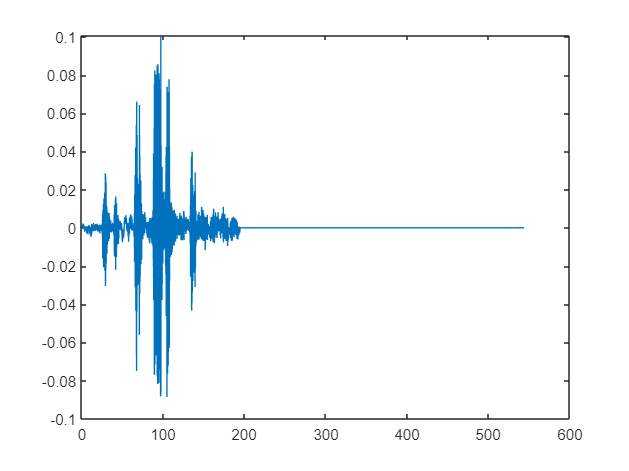

%plot(1000*[1:length(Xmattest(:,1,1))]./Fs,Xmattest(:,1,1))

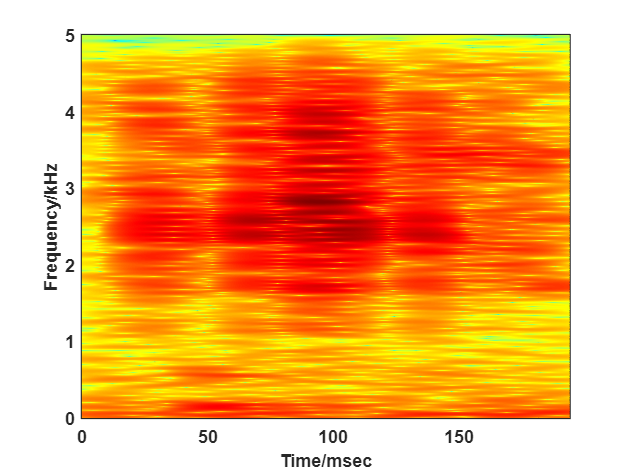

%plotspectrogram(SStot(:,:,1),Fs)

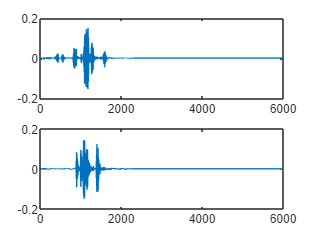

% Inspect the false evaluations 
load Xmat13B04.mat
X = Xmat13B04_2; % change this to the particular strophe you want to inspect
k = 1; % change this to the particular index you want to inspect
x = X(:,k,1);
y = X(:,k+1,1);
figure
subplot(211)
plot(x)
subplot(212)
plot(y)

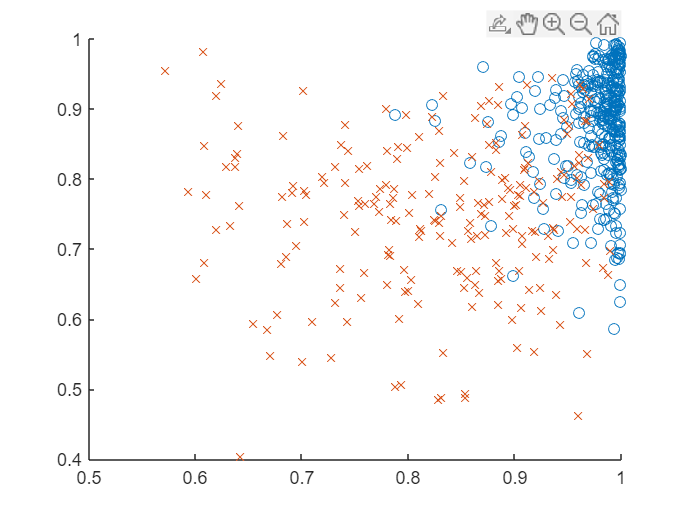

% scatter plot for the whole song
x = sspcc(:,1); % This is a list of the max(crossCorrelations
y = sspcc(:,2);
ev = sspcc(:,3);
%ev = x.*y;
v = find(ev >= 0.7);
v2 = find(ev < 0.7);
scatter(x(v),y(v),'o')
hold on
scatter(x(v2),y(v2),'x')
hold off

x = rand(1,100000)

x =     0.2734    0.1350    0.1365    0.9559    0.9370    0.1638    0.8581    0.7305    0.6603    0.3930    0.7376    0.4947    0.9157    0.6483    0.6002    0.4724    0.0438    0.1890    0.9169    0.6470    0.2686    0.0514    0.5789    0.8270    0.2814    0.7915    0.2932    1.0000    0.9053    0.4919    0.7322    0.8440    0.3371    0.4732    0.4152    0.5586    0.1234    0.4819    0.0249    0.7925    0.0615    0.3349    0.7337    0.8840    0.1386    0.5714    0.9334    0.1888    0.3354    0.8865


y = rand(1,100000)

y =     0.4962    0.6020    0.9712    0.8644    0.3179    0.8985    0.8251    0.6686    0.1602    0.9874    0.4969    0.7508    0.5013    0.4948    0.3134    0.3259    0.2645    0.7580    0.2464    0.1577    0.7195    0.9426    0.7582    0.6137    0.6791    0.8906    0.5737    0.9328    0.9645    0.8288    0.8338    0.6360    0.0755    0.8598    0.8046    0.8966    0.8789    0.3092    0.8544    0.4069    0.6995    0.7661    0.2402    0.0353    0.9491    0.1599    0.9297    0.7640    0.8038    0.2552


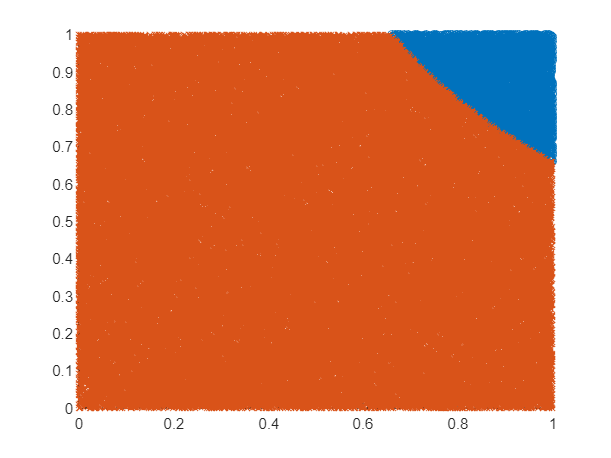

mul = x.*y;
v = find(mul >= 0.66);
v2 = find(mul < 0.66);
scatter(x(v),y(v),'o')
hold on
scatter(x(v2),y(v2),'x')
hold off

function [result, r1, r2] = spcc_similarity(Sx,Sy)
        % This functioins uses the spectrogram cross correalation (SPCC) to
        % calulate a similarity measure between two signals.

        % Input: spectrogram of each signal

        % Output: max(crossCorr_{mtx,mty}(tau)) *max(crossCorr_{mfx,mfy}(tau)) 

        % Calculate the marginals
        mtx = sum(Sx); % marginal along time for x
        mty = sum(Sy); 
        mfx = sum(Sx,2); % marginal along frequency for x
        mfy = sum(Sy,2);

        % Cross correlation in time and frequency marginals
        XCt = xcorr(mtx,mty,700,'normalized');
        XCf = xcorr(mfx,mfy,700,'normalized');
        
        r1 = max(XCt);
        r2 = max(XCf);
        result = max(XCt)*max(XCf); % This is the SPCC similarity measure
end